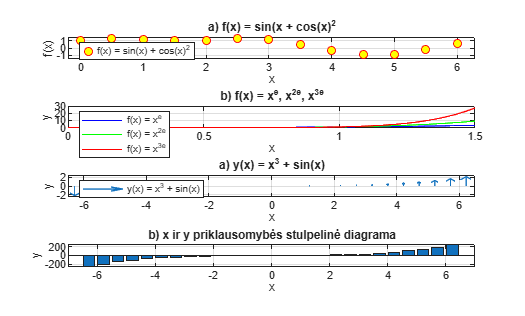

clear
close all

x=0:0.5:2*pi;
f=sin(x)+cos(x).^2;

figure;
subplot(4,1,1);
plot(x,f,'o','MarkerEdgeColor','r','MarkerFaceColor','y');

xlabel('x');
ylabel('f(x)');
title('a) f(x) = sin(x + cos(x)^2');
legend('f(x) = sin(x) + cos(x)^2','Location','southwest');
axis([-0.2 2*pi -1.5 1.5]);
grid on;

x1=0:0.01:1.5;
f1=x1.^exp(1);
f2=x1.^(2*exp(1));
f3=x1.^(3*exp(1));

subplot(4,1,2);

plot(x1,f1,'b'); hold on;
plot(x1,f2,'g'); hold on;
plot(x1,f3,'r');

xlabel('x');
ylabel('y');
title('b) f(x) = x^e, x^{2e}, x^{3e}');
legend('f(x) = x^e', 'f(x) = x^{2e}', 'f(x) = x^{3e}','Location','northwest');
axis([0 1.5 -0.5 30]);
grid on;

x2=-2*pi:0.5:2*pi;
f4=x2.^3+sin(x2);

subplot(4,1,3);

u=zeros(size(x2));

quiver(x2,u,u,f4);
xlabel('x');
ylabel('y');
title('a) y(x) = x^3 + sin(x)');
legend('y(x) = x^3 + sin(x)','Location','northwest');
axis([-6.5 6.5 -2.5 2.5]);
grid on;

subplot(4,1,4);

bar(x2,f4);

xlabel('x');
ylabel('y');
title('b) x ir y priklausomybės stulpelinė diagrama');
axis([-7 7 -260 260])
grid on;

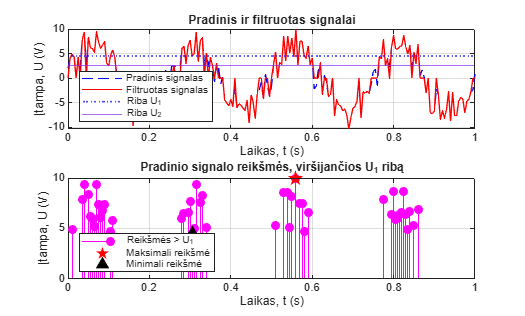

%%PAPILDOMA
clear all
t = 0:0.005:1;
A=7;
f=4;
o=2;
U1=4.5;
U2=2.5;
n=o*randn(size(t));
s=A*sin(2*pi*f*t)+n;

reiksmesvirs = s(s>U1);

sfilt=s;
sfilt(abs(sfilt)<U2) = 0;

dydis=length(s);

dydis2=length(reiksmesvirs);

didziausia = max(sfilt);
%%------------------------------
close all
figure;

subplot(2,1,1);

plot(t,s,'--b'); hold on;
plot(t,sfilt,'-r');
yline(U1,':b', 'LineWidth', 1.25);
yline(U2,'Color', [0.54, 0.17, 0.89]);

title('Pradinis ir filtruotas signalai');
xlabel('Laikas, t (s)');
ylabel('Įtampa, U (V)');
grid on;
xlim([0 1]);
legend('Pradinis signalas', 'Filtruotas signalas', 'Riba U_1', 'Riba U_2', 'Location', 'southwest');

subplot(2,1,2);


ind_virs = find(s > U1);
t_virs = t(ind_virs);
reiksmesvirs = s(ind_virs);

min_val = min(reiksmesvirs);
max_val = max(reiksmesvirs);

min_idx = find(reiksmesvirs == min_val);
max_idx = find(reiksmesvirs == max_val);

stem(t_virs, reiksmesvirs, 'filled', 'm'); hold on;

plot(t_virs(max_idx), max_val, 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r');
plot(t_virs(min_idx), min_val, '^k', 'MarkerSize', 8, 'MarkerFaceColor', 'k');

title('Pradinio signalo reikšmės, viršijančios U_1 ribą');
xlabel('Laikas, t (s)');
ylabel('Įtampa, U (V)');
grid on;
xlim([0 1]);
legend('Reikšmės > U_1', 'Maksimali reikšmė', 'Minimali reikšmė', 'Location', 'southwest');